# Chap 8 Image generation

[llms-with-matlab/doc/functions/openAIImages.generate.md at main · matlab-deep-learning/llms-with-matlab](https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/doc/functions/openAIImages.generate.md)

### Dall-E 3 Generation

[llms-with-matlab/examples/UsingDALLEToGenerateImages.md at main · matlab-deep-learning/llms-with-matlab](https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/examples/UsingDALLEToGenerateImages.md)

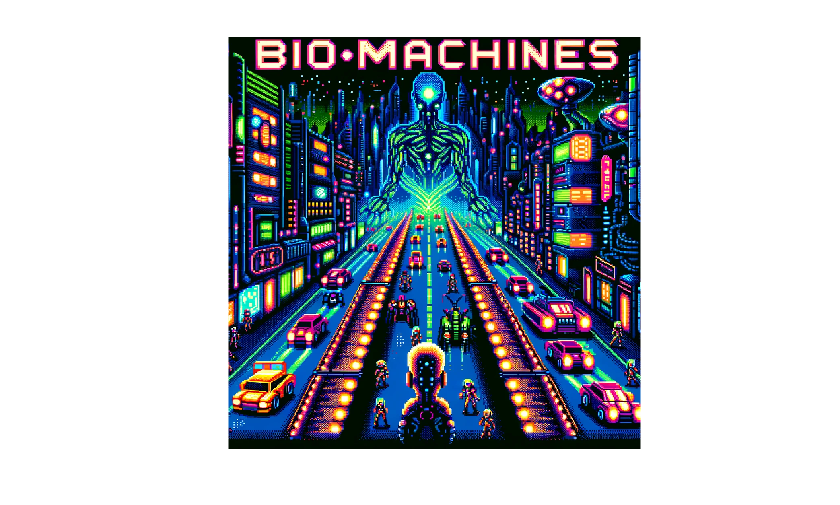

model = openAIImages(ModelName="dall-e-3"); % By default Dall-E 2
prompt = "An 8-bit pixelated game side scroller called biomachines." + ...
    "cyberpunk story about humans being biological machines." + ...
    "Pixelated like NES. Bright colors. Huge glowing pixels. Pixelated.";
Im = generate(model,prompt,"Size","1024x1024");
imshow(Im{1})

% Save image as png
imwrite(Im{1}, "biomachines-8bits_1024x1024.png");

### Edits

[llms-with-matlab/examples/UsingDALLEToEditImages.md at main · matlab-deep-learning/llms-with-matlab](https://github.com/matlab-deep-learning/llms-with-matlab/blob/main/examples/UsingDALLEToEditImages.md)

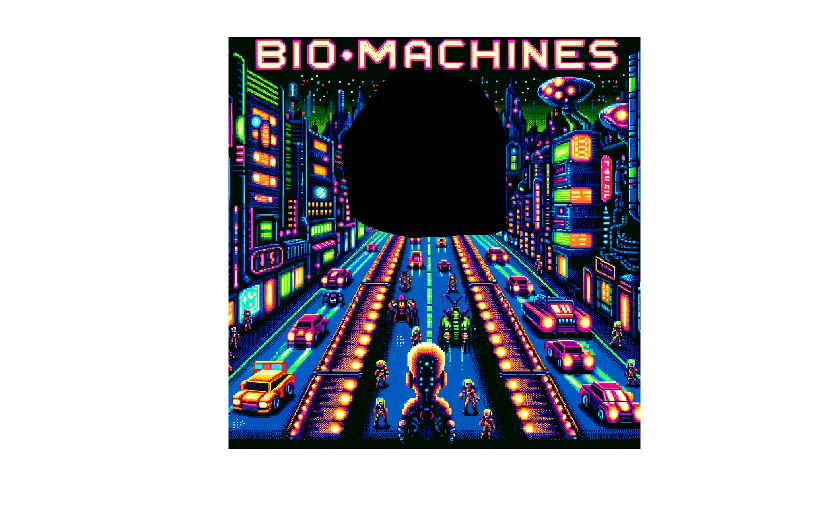

maskImagePath = "mask.png";
imshow(maskImagePath)

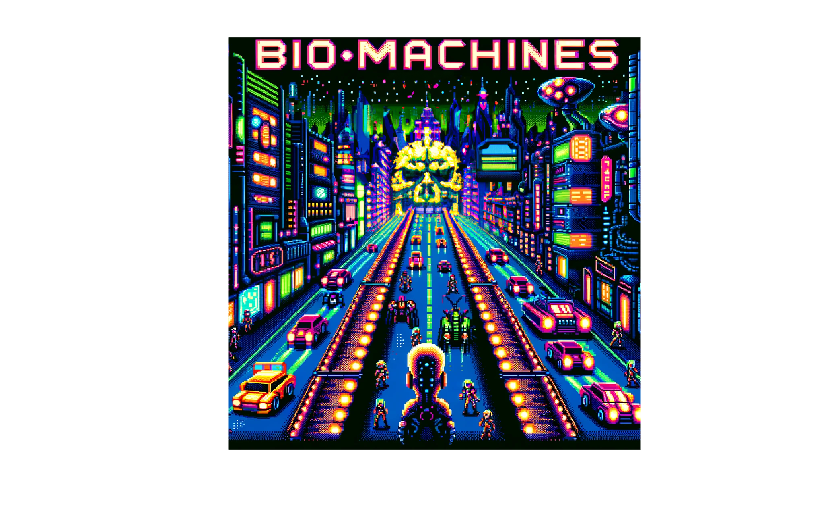

mdl = openAIImages(ModelName="dall-e-2");
imagePath = "biomachines-8bits_1024x1024.png";
editPrompt = "Terminator giant skull face in a cyberpunk 8 bits pixelated game";
[images,resp] = edit(mdl, imagePath, editPrompt, MaskImagePath=maskImagePath);
if isfield(resp.Body.Data,'data')
    figure
    imshow(images{1});
else
    disp(resp.Body.Data.error)
end

### Variations

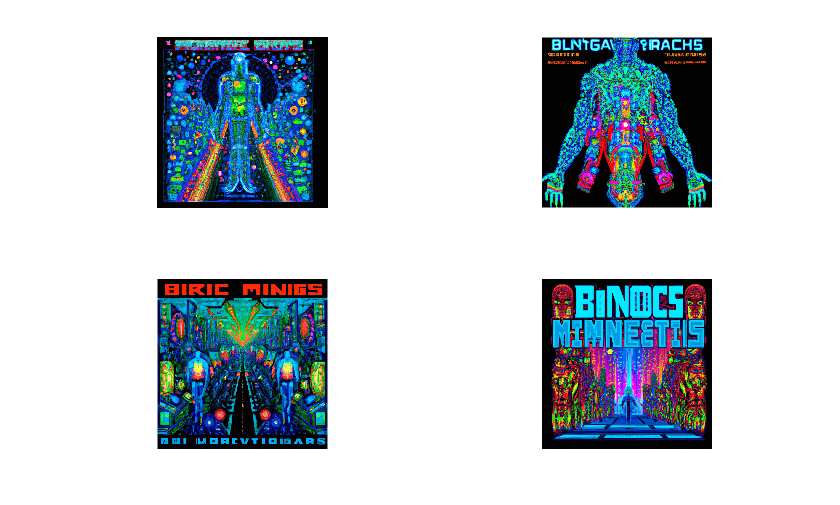

[images,resp] = createVariation(mdl, imagePath, NumImages=4);
if ~isempty(images)
    tiledlayout('flow')
    for ii = 1:numel(images)
        nexttile
        imshow(images{ii})
    end
else
    disp(resp.Body.Data.error)
end

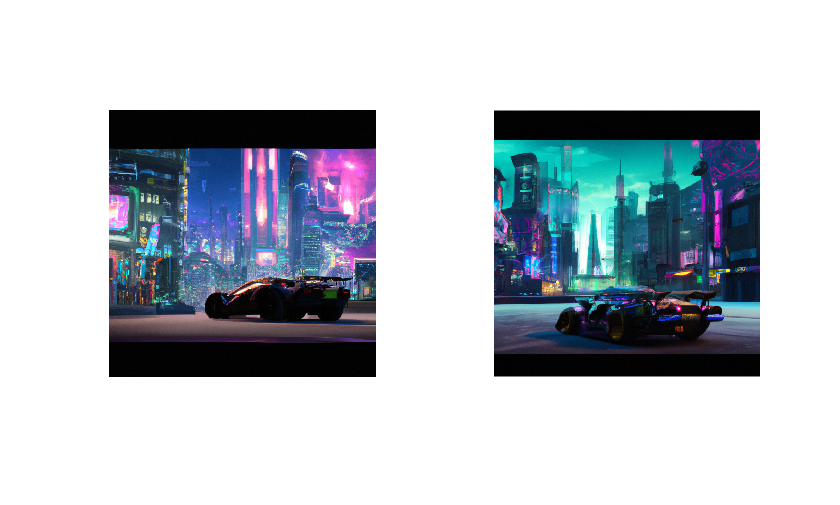

imagePath = "biomachines_car.png";
[images,resp] = createVariation(mdl, imagePath, NumImages=2);
if ~isempty(images)
    tiledlayout('flow')
    for ii = 1:numel(images)
        nexttile
        imshow(images{ii})
    end
else
    disp(resp.Body.Data.error)
end